# Matlab Project Assignment

# Task #01

The data $x\left\lbrack n\right\rbrack =\theta n+w\left\lbrack n\right\rbrack$for $n=0,1,2,\ldotp \ldotp \ldotp N-1$ are observed, where $w\left\lbrack n\right\rbrack$ is zero-mean WGN with variance $\sigma^2$.

The objective is to estimate $\theta$.

## Showing that the estimator $\theta =\frac{\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack n}{\sum_{n=0}^{N-1} n^2 }\;$  is efficient by Monte Carlo (MC) simulation.

close all ; clear all ; clc ;


MC = 10000 ; % Number of Monte Carlo loops
N = 10 ; % Number of samples in the data
n = [0:N-1] ; % row vector to represent the index of each sample
noise_var = 2 ; % Variance of the AWGN
theta = 10 ; % Mean


noise = 0 + randn(MC,N)*sqrt(noise_var) ; % w[n] ==> AWGN with zero mean and variance = noise_var
signal = theta*n ; % theta*n ==> signal of interset
x = signal + noise ; % captured samples with MC rows and N columns

estimate = sum(x.*n,2)/sum(n.^2) ; % (sum of wiegthed samples / sum of squared indecies)

mean_estimate = mean(estimate) % mean of the estimate along MC loops

mean_estimate = 9.9998

var_estimate = var(estimate) % variance of the estimate along MC loops

var_estimate = 0.0071


CRLB = (noise_var)/(sum(n.^2)) % (variance / sum of squared indecies )

CRLB = 0.0070



% The estimate is efficient ("good enough") if the error in its statistics is less than some percentage (3% in this test)
if abs((mean_estimate-theta)/theta)<.03 && abs((var_estimate-CRLB)/CRLB)<.03
    disp('The estimator is an efficeint estimator ')
else
    disp('The estimator is not an efficeint estimator ')
end

The estimator is an efficeint estimator 


## Generating figure that shows that simulated and theoretical probability density functions agree for the previous estimator.

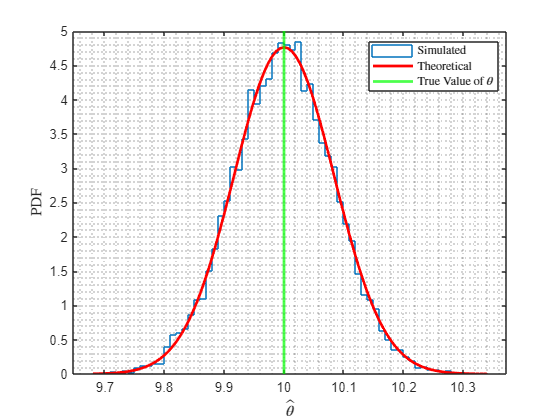

figure

H = histogram(estimate,'Normalization','pdf','DisplayStyle',"stairs") ;
hold on
x2 = linspace(H.BinLimits(1),H.BinLimits(2),100) ; % range of x for theoretical results

theor_PDF = normpdf(x2,theta,sqrt(CRLB)) ;
plot(x2, theor_PDF,'r-','Linewidth',2) ;

xline(theta,'-g','Linewidth',2) ;

grid minor
legend('Simulated','Theoretical','True Value of $\theta$','interpreter','latex','Location','best') ;
xlabel('$\hat{\theta}$','interpreter','latex') ;
ylabel('PDF','interpreter','latex') ;


%%% saving plot
%% saveas(gca,'two_PDFs.pdf');
% export_fig two_PDFs.pdf
% system('pdfcrop two_PDFs.pdf two_PDFs.pdf');

## What happens when N = 1 and N → ∞ ?

% close all ; clear all ; clc ;
MC = 10 ; % Number of Monte Carlo loops (reduced to speed up the iterations)
N = 10.^[0:7] ; % Number of samples in the data (swept)
noise_var = 2 ; % Variance of the AWGN
theta = 10 ; % Mean

for ii = 1:length(N) % used as an index to sweep N
    n = [0:N(ii)-1] ; % row vector to represent the index of each sample

    x = theta*n + randn(MC,N(ii))*sqrt(noise_var)  ; % captured samples with MC rows and N(ii) columns

    estimate = sum(x.*n,2)/sum(n.^2) ; % (sum of wiegthed samples / sum of squared indecies)

    mean_estimate(ii) = mean(estimate) ; % mean of the estimate along MC loops
    var_estimate(ii) = var(estimate) ; % variance of the estimate along MC loops

    CRLB(ii) = (noise_var)/(sum(n.^2)) ; % (variance / sum of squared indecies )
end
format long
mean_estimate

mean_estimate =                  NaN  10.025149688833483   9.998238217515659   9.999998553326240   9.999998585471937  10.000000018113194   9.999999999526327  10.000000000026077


var_estimate

var_estimate =                  NaN   0.006266279213217   0.000012346504144   0.000000006148877   0.000000000005927   0.000000000000008   0.000000000000000   0.000000000000000


CRLB

CRLB =                  Inf   0.007017543859649   0.000006091061367   0.000000006009011   0.000000000006001   0.000000000000006   0.000000000000000   0.000000000000000


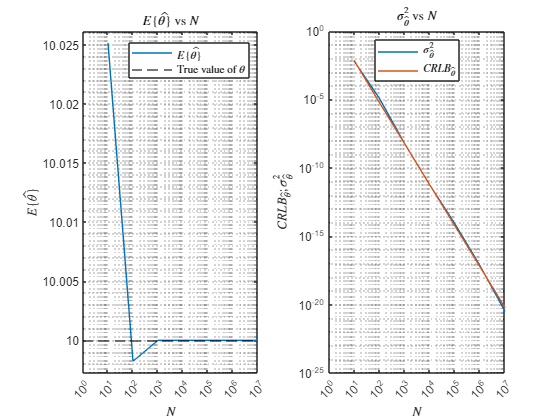


% plotting spagetti 
subplot(1,2,1)
loglog(N,mean_estimate)
hold on 
yline(theta,'k--')
hold off
ylim([0.9999*min(mean_estimate) 1.0001*max(mean_estimate)])
grid minor
title('$E\{\hat{\theta\}}$ vs $N$','interpreter','latex')
xlabel('$N$','interpreter','latex')
xticks(N)
ylabel('$E\{\hat{\theta\}}$','interpreter','latex')
legend('$E\{\hat{\theta\}}$','True value of $\theta$','interpreter','latex')

subplot(1,2,2)
loglog(N,var_estimate)
hold on 
loglog(N,CRLB)
hold off
grid minor
title('$\sigma^2_{\hat{\theta}}$ vs $N$','interpreter','latex')
xlabel('$N$','interpreter','latex')
xticks(N)
ylabel('$CRLB_{\hat{\theta}} ; \sigma^2_{\hat{\theta}}$','interpreter','latex')
legend('$\sigma^2_{\hat{\theta}}$','$CRLB_{\hat{\theta}}$','interpreter','latex','Location','best')



%%% saving plot
%% saveas(gca,'N_difference.pdf');
% export_fig N_difference.pdf
% system('pdfcrop N_difference.pdf N_difference.pdf');